Fs = 2500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

m = 5*cos(200*pi*t) + 10*cos(400*pi*t);
M = fftshift(fft(m));

x = 2*cos(2000*pi*t) .* m;
X = fftshift(fft(x));

z = 60*x + x.^2;
Z = fftshift(fft(z));

filter = zeros(1,length(Z));
center = 1000;
BW = 400;
filter( round(L/Fs*(center-BW/2) + L/2) :  round(L/Fs*(center+BW/2)+ L/2) ) = ones(1, L/Fs*BW + 1 );
filter( round(L/Fs*(-center-BW/2) + L/2) :  round(L/Fs*(-center+BW/2)+ L/2) ) = ones(1, L/Fs*BW + 1 );
Y = Z.*filter;

y = ifft(Y);

y = 	1.0e+03 *

   1.2750 - 0.0000i   0.9380 - 0.2565i   0.2365 - 0.1758i  -0.2148 + 0.1913i  -0.1046 + 0.4638i   0.3048 + 0.3674i   0.4998 + 0.0488i   0.2552 - 0.0932i  -0.1839 + 0.1337i  -0.4217 + 0.4939i  -0.3327 + 0.5944i  -0.1211 + 0.3354i  -0.0123 + 0.0250i   0.0123 + 0.0250i   0.1211 + 0.3354i   0.3327 + 0.5944i   0.4217 + 0.4939i   0.1839 + 0.1337i  -0.2552 - 0.0932i  -0.4998 + 0.0488i  -0.3048 + 0.3674i   0.1046 + 0.4638i   0.2148 + 0.1913i  -0.2365 - 0.1758i  -0.9380 - 0.2565i  -1.2750 + 0.0000i  -0.9380 + 0.2565i  -0.2365 + 0.1758i   0.2148 - 0.1913i   0.1046 - 0.4638i  -0.3048 - 0.3674i  -0.4998 - 0.0488i  -0.2552 + 0.0932i   0.1839 - 0.1337i   0.4217 - 0.4939i   0.3327 - 0.5944i   0.1211 - 0.3354i   0.0123 - 0.0250i  -0.0123 - 0.0250i  -0.1211 - 0.3354i  -0.3327 - 0.5944i  -0.4217 - 0.4939i  -0.1839 - 0.1337i   0.2552 + 0.0932i   0.4998 - 0.0488i   0.3048 - 0.3674i  -0.1046 - 0.4638i  -0.2148 - 0.1913i   0.2365 + 0.1758i   0.9380 + 0.2565i


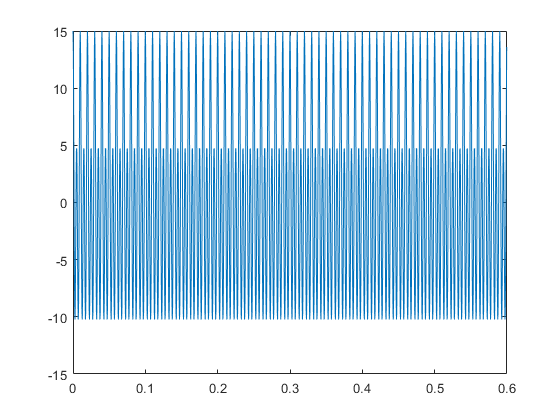



plot(t, m)

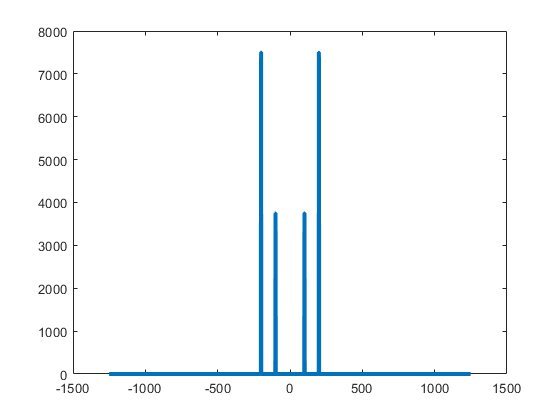

plot(Fs/L*(-L/2:L/2-1),abs(M),"LineWidth",3)

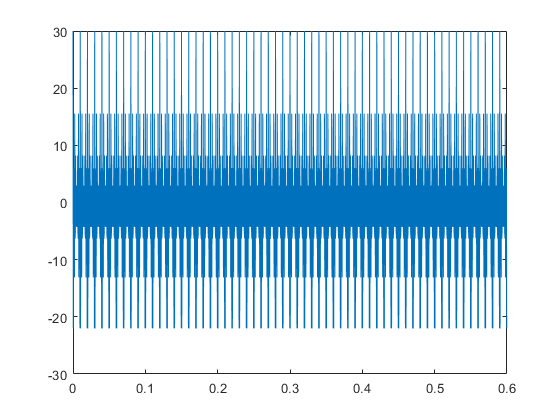


plot(t, x)

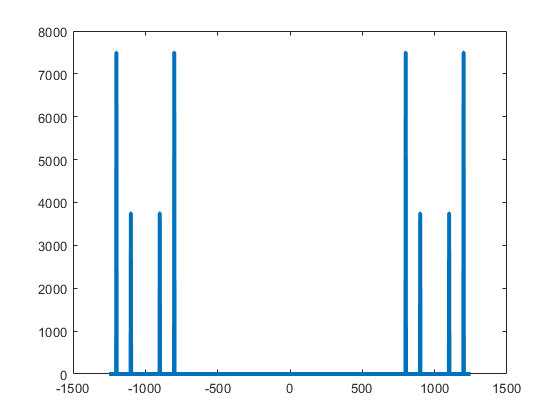

plot(Fs/L*(-L/2:L/2-1),abs(X),"LineWidth",3)

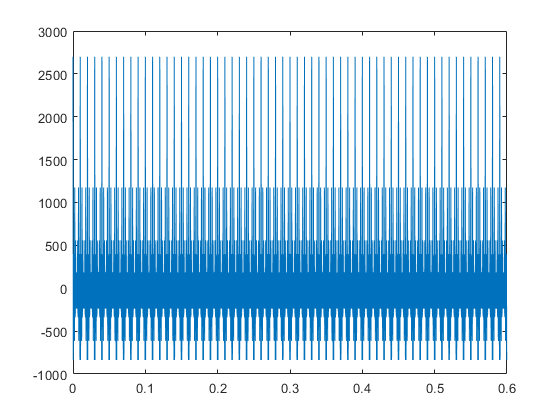


plot(t, z)

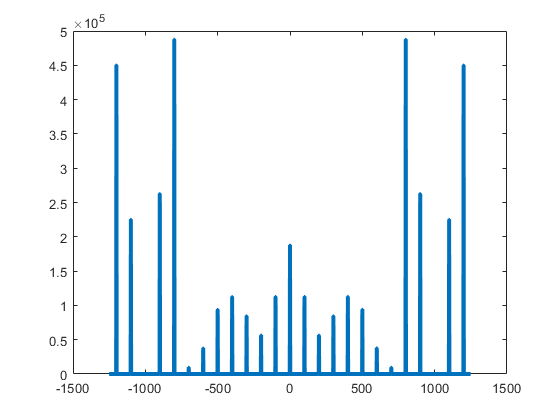

plot(Fs/L*(-L/2:L/2-1),abs(Z),"LineWidth",3)

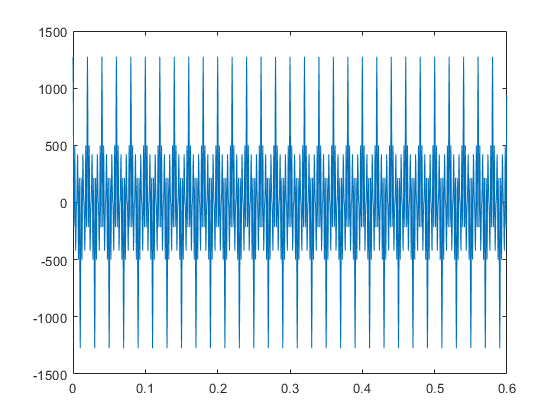


plot(t, y)

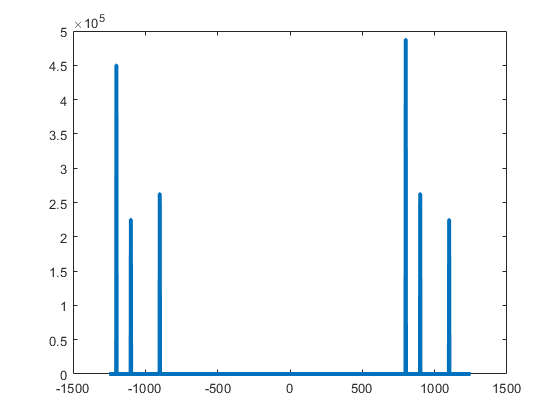

plot(Fs/L*(-L/2:L/2-1),abs(Y),"LineWidth",3)